# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Oct-2021 00:26:35

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Лист1";
opts.DataRange = "K2:L46";

% Specify column names and types
opts.VariableNames = ["V_3", "A_3"];
opts.VariableTypes = ["double", "double"];

% Import the data
Untitled1 = readtable("C:\Users\Marina\Documents\Без имени 1.xlsx", opts, "UseExcel", false)

Untitled1 = 45×2 table
     V_3       A_3  
    ______    ______

    -24.96    -68.07
       -22    -66.16
    -19.04    -64.17
    -16.02     -61.9
    -13.05     -58.4
       -10    -52.16
    -10.08    -52.09
     -8.04    -45.25
     -6.12     -36.4
     -4.01    -23.73
     -3.01    -17.04
     -2.96     -16.8
     -2.05      -9.7
         0     -5.71
     -0.23     -4.06
         0     -2.68


hold on
grid on
grid("minor")
V_3 = [ -24.96
-22
-19.04
-16.02
-13.05
-10
-10.08
-8.04
-6.12
-4.01
-3.01
-2.96
-2.05
0
-0.23
0
-1.1
-1
-0.9
-0.84
-0.74
-0.51
-0.39
0.1
-0.3
0.13
0.15
-0.15
-0.1
0.5
0.83
0.9
1
2.07
2.96
4.03
6.01
7.99
9.98
12.99
16.09
19
22.1
24.96
];
A_3 = [-68.07
-66.16
-64.17
-61.9
-58.4
-52.16
-52.09
-45.25
-36.4
-23.73
-17.04
-16.8
-9.7
-5.71
-4.06
-2.68
-2.57
-1.83
-1.06
-0.51
0.19
2
2.92
3.4
3.57
3.59
3.8
4.7
5.11
6.38
8.9
9.57
10.33
18.74
25.3
32.66
44.69
54.06
61.17
68.03
72.05
74.63
76.96
79.26

]-3.37;
a = [-23.73
-17.04
-16.8
-9.7
-5.71
-4.06
-2.68
-2.57
-1.83
-1.06
-0.51
0.19
2
2.92
3.4
3.57
3.59
3.8
4.7
5.11
6.38
8.9
9.57
10.33
18.74
25.3]-3.37

a =   -27.1000
  -20.4100
  -20.1700
  -13.0700
   -9.0800
   -7.4300
   -6.0500
   -5.9400
   -5.2000
   -4.4300


b = [
-4.01
-3.01
-2.96
-2.05
0
-0.23
0
-1.1
-1
-0.9
-0.84
-0.74
-0.51
-0.39
0.1
-0.3
0.13
0.15
-0.15
-0.1
0.5
0.83
0.9
1
2.07
2.96
]

b =    -4.0100
   -3.0100
   -2.9600
   -2.0500
         0
   -0.2300
         0
   -1.1000
   -1.0000
   -0.9000


x = [16.09
19
22.1
24.96];
y = [ 72.05
74.63
76.96
79.26]-3.37;
x_1 = [ -24.96
-22
-19.04
-16.02
    ];
y_1 = [-68.07
-66.16
-64.17
-61.9
    ]-3.37;
xlim([0;25]);
coeff_1 = polyfit(x,y,1)

coeff_1 =     0.8063   55.7966


coeff_2 = polyfit(x_1,y_1,1)

coeff_2 =     0.6885  -54.3273


coeff_3 = polyfit(b,a,1)

coeff_3 =     6.7264    0.0039


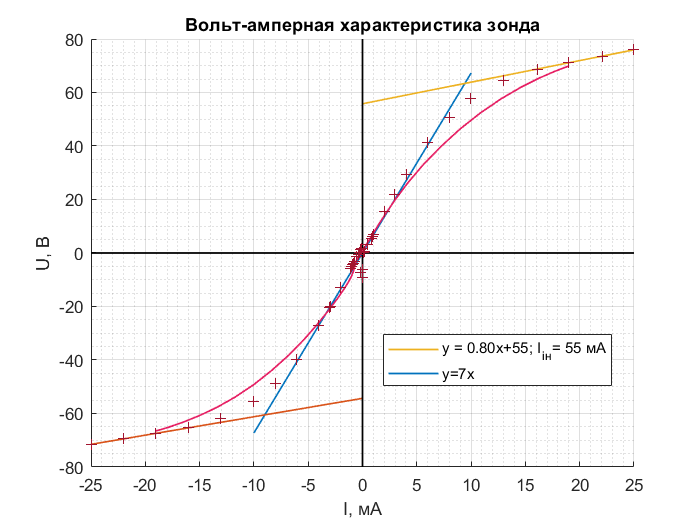

y1 = 0;
xi = min(-10):0.1:max(10);
for k=0:1
    y1 = y1 + coeff_3(1-k+1) * xi.^k;
end
gr_3 = plot(xi, y1,"LineWidth",1); 
y1 = 0;
xi = min(-25):0.1:max(0);
for k=0:1
    y1 = y1 + coeff_2(1-k+1) * xi.^k;
end
gr_2 = plot(xi, y1,"LineWidth",1); 
y1 = 0;
xi = min(0):0.1:max(25);
for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1,"LineWidth",1); 
y_0 = [0,0];
x_0 = [-25,25];
y_o=[-150;150];
x_o = [0,0];
plot(x_o,y_o,"LineWidth",1,"Color","black")
plot(x_0,y_0,"LineWidth",1,"Color","black")
V_3_S = smoothdata(V_3,'gaussian',15);
A_3_S = smoothdata(A_3,'gaussian',15);
plot(V_3_S,A_3_S,"LineWidth",1,"Color",[0.9 0.108 0.38]);
scatter(V_3, A_3, "Marker","+","MarkerEdgeColor","flat");
title("Вольт-амперная характеристика зонда")
xlabel('I, мА')
ylabel('U, В')
legend([gr_1, gr_3],"y = 0.80x+55; I_{iн}= 55 мА","y=7x","Location","best")
xlim([-25.0 25.0])
ylim([-80 80])

## Clear temporary variables

clear opts